clc
close all
clearvars
p = parselog("C:\Users\Tomaso\Desktop\data_wind_tunnel\21_12_15__21_16_32.data");
ac_data = p.aircrafts.data;
addpath(genpath('C:\Users\Tomaso\Desktop\Thesis\main\RC Testbench Data'))
addpath(genpath('C:\Users\Tomaso\Desktop\Thesis\main\sw'))

%%%%%%%%%% DOUBLET %%%%%%%%%%%%%%%%%%%%%%%%%%%
t_doublet = ac_data.DOUBLET.timestamp;
active_d  = ac_data.DOUBLET.doublet_active;
axis_d    = ac_data.DOUBLET.doublet_axis;
amp_d     = ac_data.DOUBLET.doublet_amplitude;
%%%%%%%%%% ROTORCRAFT FP %%%%%%%%%%%%%%%%%%%%%
t_RFP     = ac_data.ROTORCRAFT_FP.timestamp;
theta_RFP = ac_data.ROTORCRAFT_FP.theta;
%%%%%%%%%% Wing Rot      %%%%%%%%%%%%%%%%%%%%%
wing_angle= ac_data.ROT_WING_CONTROLLER.wing_angle_deg;
%%%%%%%%%% FLIGHT PLAN   %%%%%%%%%%%%%%%%%%%%%
block_idx = ac_data.ROTORCRAFT_NAV_STATUS.cur_block;

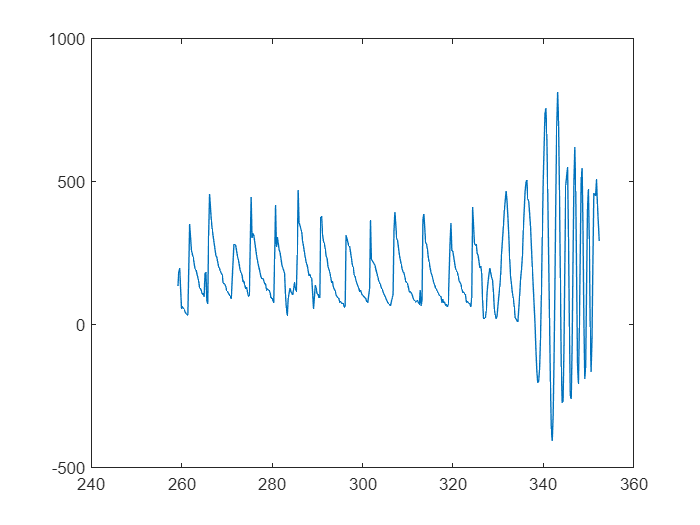

t_active_doublet = t_doublet(active_d==1 & axis_d==0 & amp_d==110);
range = t_range(t_RFP,[min(t_active_doublet) max(t_active_doublet)]);
plot(t_RFP(range),theta_RFP(range))